pds = parquetDatastore("HToEleEle_m100To5115_pT20To150_ctau0To3_eta0To1p4_RHAnalyzer_validation_0.parquet");
transformed_pds = transform(pds,@table_to_graph)

transformed_pds =   TransformedDatastore with properties:

      UnderlyingDatastores: {matlab.io.datastore.ParquetDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "dat"    "asc"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp3"    "mp4"    "m4a"]
                Transforms: {[@table_to_graph]}
               IncludeInfo: 0


preview(transformed_pds)

ans = 1×21 table
       coords0          coords1       edge_index_from    edge_index_to          pT               dz               d0              ECAL             HCAL             BPIX1            BPIX2            BPIX3            TIB1             TIB2             TOB1             TOB2         y      am       apt      ieta    iphi
    _____________    _____________    _______________    ______________    _____________    _____________    _____________    _____________    _____________

ev1 = read(transformed_pds);

MATLAB has experienced a low-level graphics error, and may not have drawn correctly.
Read about what you can do to prevent this issue at Resolving Low-Level Graphics Issues then restart MATLAB.
To share details of this issue with MathWorks technical support,
please include <a href="file:/home/colin/jogl.ex.8672">this file</a> with your service request.


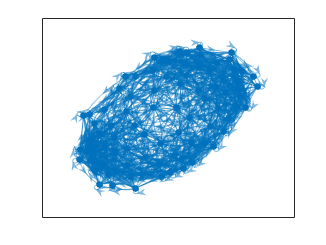

index_from = cell2mat(ev1.edge_index_from);
index_to = cell2mat(ev1.edge_index_to);
adj = zeros(length(cell2mat(ev1.pT)));
for i=1:length(index_from)
    adj(index_from(i)+1,index_to(i)+1)=1;
end
g1 = digraph(adj);
plot(g1,"NodeLabel",[])